4.

%a)
%i)
N = 1e5;

pecas = rand(5,N);
defeitos = pecas < 0.30;
A = zeros(1,N);
for i = 1:N
    nDefeitos = sum(defeitos(1:5,i));
    A(i) = nDefeitos;
end

P0 = sum(A == 0) / N

P0 = 0.1685

P1 = sum(A == 1) / N

P1 = 0.3571

P2 = sum(A == 2) / N

P2 = 0.3123

P3 = sum(A == 3) / N

P3 = 0.1316

P4 = sum(A == 4) / N

P4 = 0.0280

P5 = sum(A == 5) / N

P5 = 0.0026

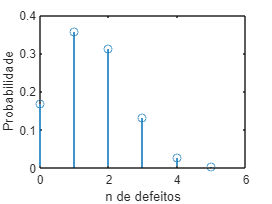


x = 0:5;
pX = [P0 P1 P2 P3 P4 P5];

stem(x,pX)
xlabel('n de defeitos')
ylabel('Probabilidade')

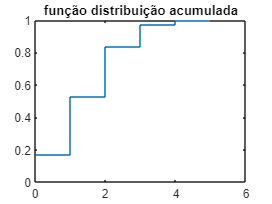



%ii)
FDistAcum = zeros(1,length(pX));
for i = 1:length(pX)
    %for j = 1:i
        %FDistAcum(i) = FDistAcum(i) + pX(j); %FDistAcum(i) = soma de px(1:i)
    %end
    FDistAcum(i) = sum(pX(1:i));
end

stairs(x,FDistAcum) %F(x) = somatorio(1:x) pX
title("função distribuição acumulada")



%iii)
fprintf('iii. P0 + P1 + P2 = %f', FDistAcum(3)) %2 + 1 (array começa em 1)

iii. P0 + P1 + P2 = 0.837830



%b)
%i)
pX_teorico = zeros(1,6);
for i = 0:5
    pX_teorico(i+1) = prob_teorica(i,5,0.3); %(n de coroas, numero de moedas, chance de vir coroa)
end
fprintf("P0 = %f\nP1 = %f\nP2 = %f\nP3 = %f\nP4 = %f\nP5 = %f",pX_teorico(1:6))

P0 = 0.168070
P1 = 0.360150
P2 = 0.308700
P3 = 0.132300
P4 = 0.028350
P5 = 0.002430

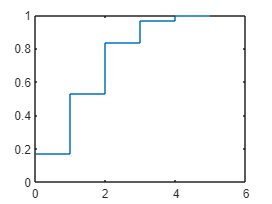

FDistAcum_teorico = zeros(1,length(pX));

for i = 1:length(pX_teorico)
    FDistAcum_teorico(i) = sum(pX_teorico(1:i));
end
stairs(x,FDistAcum_teorico)


fprintf('ii. P0 + P1 + P2 = %f', FDistAcum_teorico(3)) %2 + 1 (array começa em 1)

ii. P0 + P1 + P2 = 0.836920